## MATLAB Live scripts demonstating aspects of Optimal Interpolation.

#### The methodology follows Chapter 4, *The spatial analysis of data fields,* in: Thompson, R.E. and W. J. Emery (2014) "Data analysis methods in physical oceanography," Elsevier, [https://doi.org/10.1016/C2010-0-66362-0](https://doi.org/10.1016/C2010-0-66362-0)

#### John L. Wilkin - jwilkin@rutgers.edu

## Exercise 1: Estimating covariance length scales from pseudo-observations of SST in the eastern Equatorial Pacific generated by sampling output from the NOAA RTOFS ocean model 

### This Live script demonstates how to compute a binned-lagged covariance function from a sample data set and use this to choose covariance length scales and signal variance appropriate to the data set. These fitted parameters are used in Exercise 2 to perform an optimal interpolation of the data. It should be stressed that if the covariance functional form of chosen length scale and other parameters do not represent the underlying data well, the interpolation can be far from "optimal".

%

### Load example data set and subsample spatially to create a set of pseudo observations

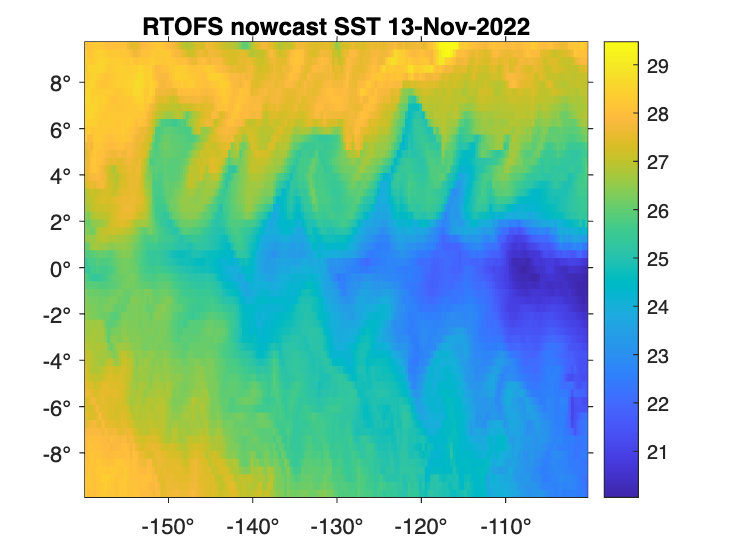

% Pseudo data are generated using example outputs from the NOAA RTOFS ocean model 
% in the equatorial Pacific showing Tropical Instability Waves

load oi_rtofs_data.mat

% Plot the full data 
pcolor(rt.lon,rt.lat,rt.sst')
shading flat
xtickformat('degrees');
ytickformat('degrees');
set(gca,'tickdir','out')
colorbar
title("RTOFS nowcast SST "+rt.date)

#### Estimate covariance length scales from data

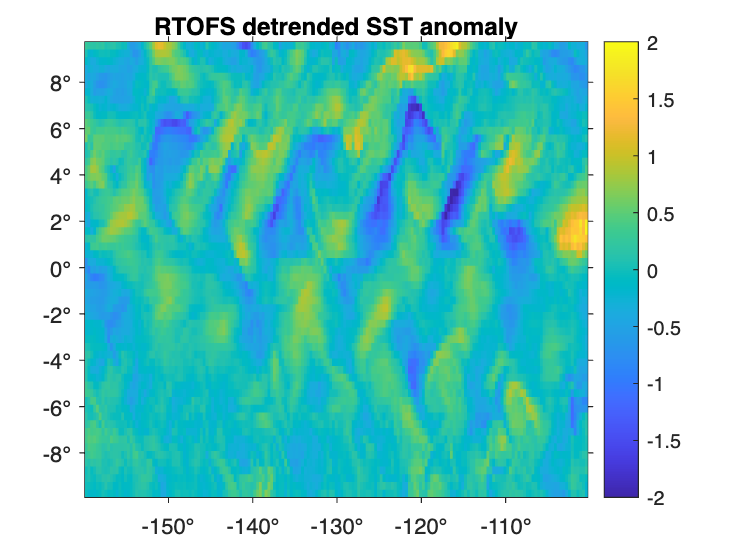

% Optimal interpolation is not optimal if the covariance scale used poorly 
% represents the true covariance of the quantity being mappped. We can use 
% the data themselves to estimate the covariance scale of a geophysical
% signal.

% Before analyzing the data to estimate covariance scales, remove long 
% wavelengths by detrending in two dimensions so as to focus on the ocean
% mesoscale 
sstanom = detrend(detrend(rt.sst)')';

% Plot spatially detrended anomaly field
pcolor(rt.lon,rt.lat,rt.sstanom')
shading flat
xtickformat('degrees');
ytickformat('degrees');
set(gca,'tickdir','out')
caxis([-2 2])
colorbar
title("RTOFS detrended SST anomaly")

#### Subsample/decimate the "truth" to prepare a data set of pseudo observations

% The data will be subsampled spatially to simulate a sparse observing 
% network, and random noise added to simulate observational error. 
% In script oi_example.mlx Optimal Interpolation will be used to explore how 
% well we can recover the original data ("truth")

% Start with the detrended SST anomaly on the full spatial domain
dataf = sstanom;

disp("Set the fraction of data to retain as pseudo observations") 

Set the fraction of data to retain as pseudo observations


frac = 0.1

frac = 0.1000


% Get set of unique random integers spanning the length of the full data set 
% and use this to subsample/decimate the true field
N = numel(dataf);
ss = randperm(N,round(frac*N));
data = dataf(ss);

% Get corresponding coordinates of the sample set
[LON,LAT] = ndgrid(rt.lon,rt.lat);
x = LON(ss);
y = LAT(ss);

% Add random noise to simulate observational error
disp("Set the magnitude of pseudo observational error to add to the data")

Set the magnitude of pseudo observational error to add to the data


e = 0.2 % degrees C

e = 0.2000

data = data + e*randn(size(data));

% Force column vectors
x = x(:);
y = y(:);
data = data(:);

#### Sample Covariance function

% Use the simulated data to infer the shape and scales of the covariance function

% It is recommended before attempting optimal interpolation to interrogate your d
% data in this way to get an objective sense of the covariance scales that 
% dominate your data. 

% Create matrices that repeat the pseudo observation coordinates: columns of x, 
% and rows of y. Then X-X' and Y-Y' will be all possible distance combinations 
% between pairs of points
X = repmat(x,[1 length(y)]);
Y = repmat(y',[length(x) 1]);
Rdd = sqrt((X-X').^2+(Y-Y').^2);

% The sample data were detrended so they have a mean of zero. The covariance 
% of the sample data is then simply 
Cdd = data*data';

% The Rdd distance matrix and C are symmetric because they repeat the
% covariances c(i,j)=c(j,i). We want only unique covariance pairs, which
% can be achieved by keeping only the upper triangle of Cdd. Create a mask
% M = 0 on lower triangle and 1 on the diagonal and upper triangle. 
% Applying this mask then eliminates repeats c(i,j)=c(j,i) i~=j
M = triu(ones(size(Rdd)));  
C = Cdd(M==1);              
R = Rdd(M==1); 

% Compute the sample covariance for values grouped into separation distance
% bins of size dr, and limit the maximum range considered to focus on the 
% ocean mesoscale. Retaining long teleconnections would bias the estimate 
% of the covariance length scale.
dr = 0.1;                % deg lon/lat
rfitmax = 6;             % deg lon/lat
C(R>rfitmax) = []; 
R(R>rfitmax) = [];

% Find range bin number
B = round(R/dr);         % unique integer index for each range bin +/-dr
B = B+1;                 % add 1 because rounding R<0.5*dr is zero

% accumarray is a handy Matlab function to construct an array by accumulation
% Find all in arg 2 (range) with a common index in arg 1 (range bin) and 
% apply operation arg 4 (take the mean)
rf = accumarray(B,R,[],@mean);
cf = accumarray(B,C,[],@mean);

% Replace covariance for bin r = 0 (actually 0 < r < dr/2) with the 
% covariance at precisely zero lag to capture sum of signal variance and 
% observation error variance
cf(1) = mean(diag(Cdd));

% Trap the case of bins having no elements
rf(cf==0) = [];
cf(cf==0) = [];

#### Fit functional forms to sample covariance 

% Use FMINSEARCH to fit the user defined covariance functional forms  
% in OI_MYCOVFUNCTIONS.m to the sample covariance. The 2nd argument to 
% FMINSEARCH is a vector [C0 A] of the starting guesses for C0 = covariance
% at r = 0, and length scale, A. The 4th and 5th arguments are the sample 
% data which are passed on to OI_MYCOVFUNCTIONS. The 6th argument is the 
% functional form (one of Gauss, Markov or Le Traon). The help on 
% FMINSEARCH and OPTIMSET explain the nonlinear parameter fitting process. 

% Starting guess assumes C0 = 1 (half the span of the data range) and
% length scale A = 3 (half the rfitmax of 6). FMINSEARCH is quite
% robust to very bad initial guesses. 
X0 = [0.5 3];

% f = a1*exp(-0.5*(r/a2)^2)
a_ga = fminsearch('oi_mycovfunctions',X0,[],rf(2:end),cf(2:end),'gauss');

% f = b1*(1+r/b2)*exp(-r/b2)
a_mk = fminsearch('oi_mycovfunctions',X0,[],rf(2:end),cf(2:end),'markov');

% f = c1*exp(-r/c2)*(1+r/c2+(r^2)/6-(r^3)/6
a_lt = fminsearch('oi_mycovfunctions',X0,[],rf(2:end),cf(2:end),'letra');

% evaluate the final fit at convergence
misfit_a = oi_mycovfunctions(a_ga,rf(2:end),cf(2:end),'gauss');
misfit_b = oi_mycovfunctions(a_mk,rf(2:end),cf(2:end),'marko');
misfit_c = oi_mycovfunctions(a_lt,rf(2:end),cf(2:end),'letra');

%% For these test data the best functional fit is consistently Le Traon
disp("For these test data the best functional"+newline...
  +"form is consistently Le Troan"+newline+newline...
  +"Le Troan function values fitted for this"+newline...
  +"test data subsample and added noise were"+newline...
  +" length scale "+num2str(a_lt(2))+newline...
  +" variance at zero lag (r=0) "+num2str(a_lt(1))+newline)

For these test data the best functional
form is consistently Le Troan

Le Troan function values fitted for this
test data subsample and added noise were
 length scale 0.89468
 variance at zero lag (r=0) 0.17277



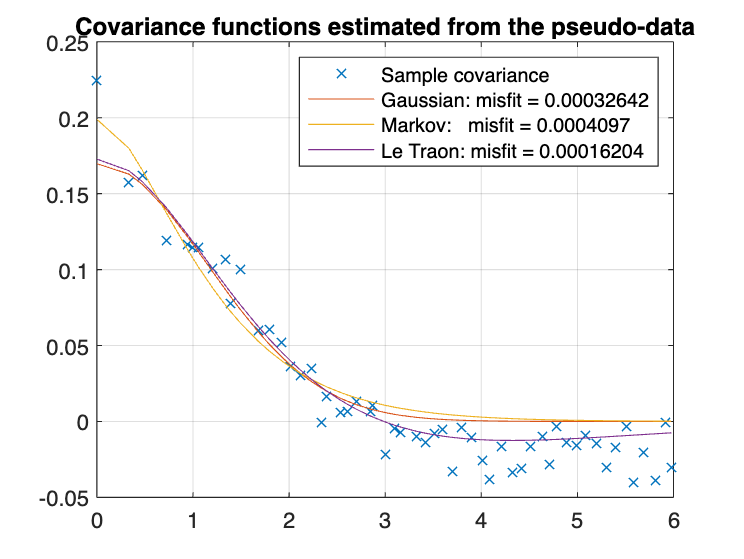


% Plot the sample covariance and the 3 fits for the different functions.
han = plot(rf,cf,'x',...
  rf,a_ga(1)*exp(-0.5*(rf/a_ga(2)).^2),...
  rf,a_mk(1)*(1+rf/(a_mk(2))).*exp(-rf/a_mk(2)),...
  rf,a_lt(1)*(1+rf/a_lt(2)+1/6*(rf/a_lt(2)).^2 -1/6*(rf/a_lt(2)).^3).*exp(-rf/a_lt(2)));
legend("Sample covariance",...
  "Gaussian: misfit = "+num2str(misfit_a),...
  "Markov:   misfit = "+num2str(misfit_b),...
  "Le Traon: misfit = "+num2str(misfit_c))
grid
title("Covariance functions estimated from the pseudo-data")

Notice that at zero lag, r=0, the sample covariance jumps up dramatically. This is because is includes the variance inherent to the geophysical signal, plus the observation error variance. The effect of observation error does not appear at lags other than zero because the pseudo error of different distinct observations is uncorrelated. This is why fitting a covariance function to actual data should always ignore the covraince of the data with itself. This can be an effective way to objectively estimate what the observation error actually is when this is uncertain. 